# Modifying Squishy Data Processing

Things we want to include:

- one matrix for all our data

- should combine with CaSO4_mixing file

- make this one big function file

a/ Calculating salt rejection  = [1-(permeate conductivity)/(average conductivity on feed side of membrane)]

perm_conductivity = 0.5; % mS
salt_rej = (1-(perm_conductivity)/mean(conductivity_list))*100 % percentage

salt_rej = 86.4868

b/ Calculate the calcium sulfate concentration at the membrane at each timestep (from input initial concentration and instantaneous recovery and including concentration polarization.)

initial_conc = 450;    % intial concentration mol/L
mem_const = 0.99;  % membrane constant (K) 

recovery = (permeate_flowrate_list./flowrate_list)*100;  %expressed in terms of percentage
mem_CaSO4_conc = (1./(1-recovery)) .* initial_conc;          % membrane CaSO4 concentration
conc_polar = mem_const * exp(permeate_flowrate_list./mean(flowrate_list)); % concentration polarization

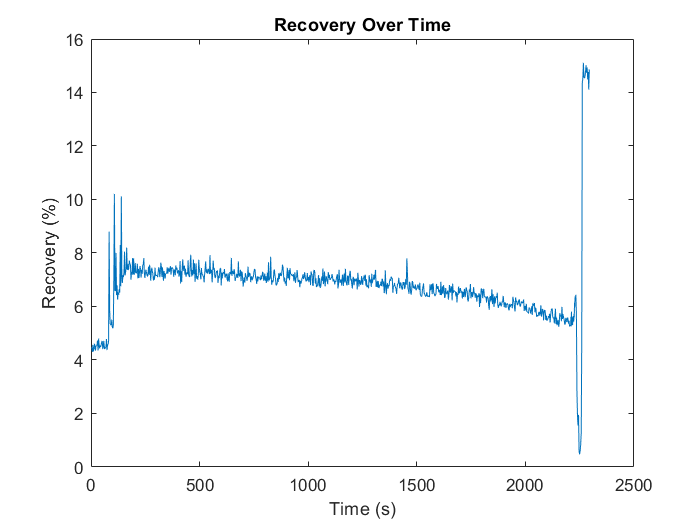

%plotting recovery
plot(time_list,recovery)
title('Recovery Over Time')
xlabel('Time (s)')
ylabel('Recovery (%)')

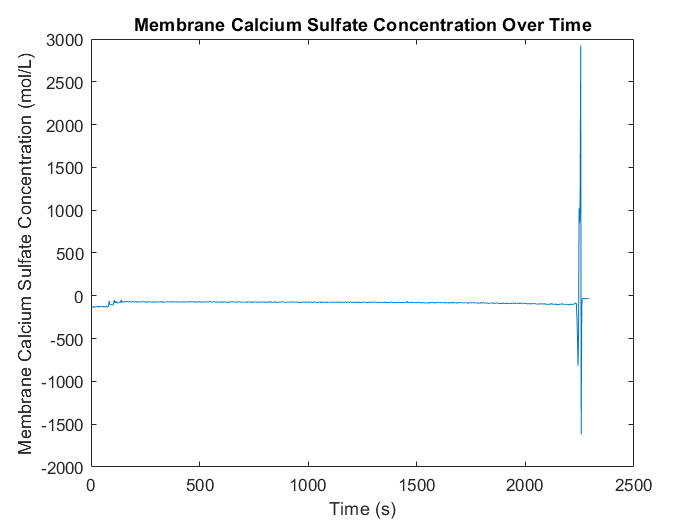


%plotting Membrane Calcium Sulfate Concentration
plot(time_list,mem_CaSO4_conc)
title('Membrane Calcium Sulfate Concentration Over Time')
xlabel('Time (s)')
ylabel('Membrane Calcium Sulfate Concentration (mol/L)')

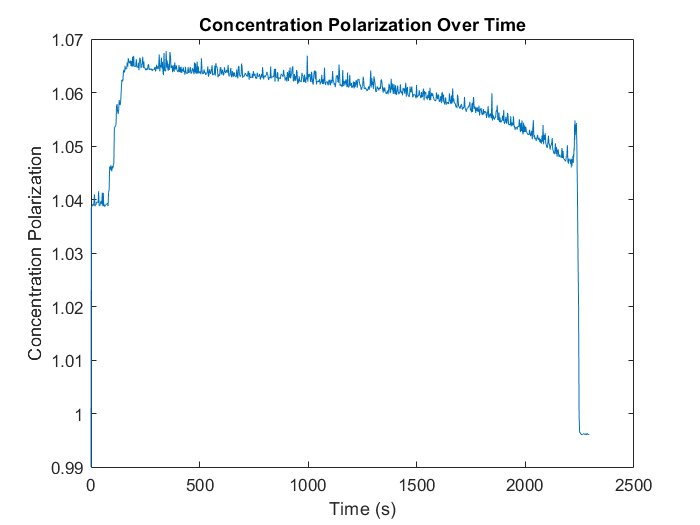


%plotting Concentration Polarization
plot(time_list,conc_polar)
title('Concentration Polarization Over Time')
xlabel('Time (s)')
ylabel('Concentration Polarization')


% title('')
% xlabel('')
% ylabel('')

c/ Calculate the saturation index of gypsum (a.k.a. calcium sulfate dihydrate) at the membrane at each timestep.

% equation in comments of doc
sat_index = 0.527 .* log(mem_CaSO4_conc) - 1.5073;

% plotting Saturation Gypsum over time
plot(time_list,sat_index)

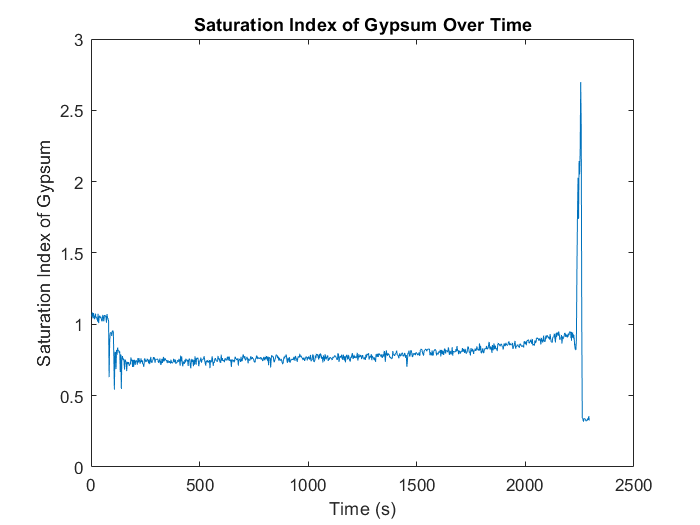

title('Saturation Index of Gypsum Over Time')
xlabel('Time (s)')
ylabel('Saturation Index of Gypsum')

d/ Calculate the nucleation induction time of gypsum at each timestep.

% ---------------------- hmmmmmmmmmmm
conc_over_time = mem_CaSO4_conc ./ time_list; %this might not be it
ind_time = 1.66*(10^6).*(exp(-0.174*mem_CaSO4_conc)); % Induction Time in seconds (s)

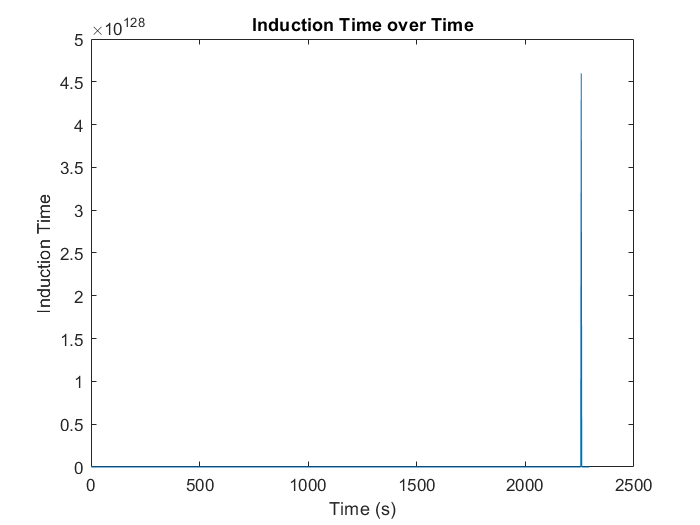

%plotting Induction Time over Time  hmmmmmmmmmm
plot(time_list,ind_time)
title('Induction Time over Time')
xlabel('Time (s)')
ylabel('Induction Time')

e/ Integrate the induction rate (i.e., the inverse of induction time) over all timesteps in each batch cycle to determine the nucleation probability per cycle

% ----------------- hmmmmmmmmm
syms ind_time C_t
f(ind_time,C_t) = 1/(ind_time*C_t)

Error using sym/subsindex (line 864)
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

fint = int(f,ind_time,C_t)
nucl_prob = int(1/(ind_time*C_t),time_list,0,500) 